**Exercise 2-1** Load the image dog.jpg and convert to grayscale. Use the FFT to compress the image at the different compression ratios as follows 

compression_rate = [1/1e1 1/1e2 1/1e3 1/3e3 1/6e3 1/1e4]

Inside of a "for loop" use  

1/compression_rate(k)

to find all frequencies with large power. 

Hint: Refer to the script "CH01_SEC02_dog_image.m" to load and plot the image "dog.jpg," and use the script "project6.mlx" to assist you in writing your own script.

Plot the error between the compressed and actual image as a function of the compression ratio. 


$$\textbf{Exercise 2-4.} \text{Use the FFT to solve the Kuramoto-Sivashinsky (KS) equation,}
\[
u_t + u_{xx} + u_{xxxx} + \frac{1}{2} u_x^2 = 0,
\]
\text{on a large domain with an initial condition } u(x,0) = \text{sech}(x). \text{ Plot the evolution.}$$


Hint: Use script "CH02_SEC03_3_FFTBurgers.m"

**Exercise 2-5** Solve for the analytic equilibrium temperature distribution using the 2D Laplace equation on an $\left\lbrack 0,L\right\rbrack \times \left\lbrack 0,H\right\rbrack$ sized rectangular domain with the following boundary conditions. 

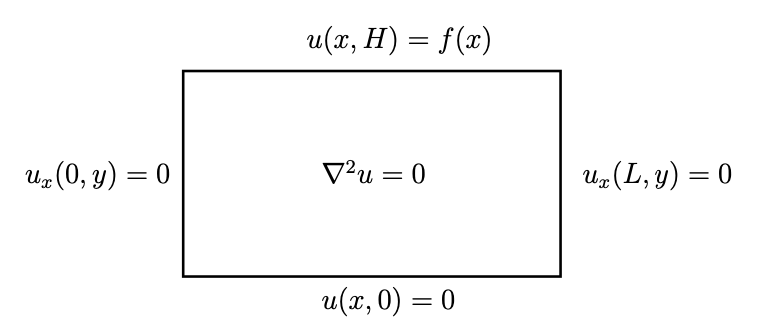

a) Left: $u_x (0,y)=0$ (insulating). 

b) Bottom: $u(x,0)=0$ (fixed temperature). 

c) Top: $u(x,H)=f(x)$ (non-zero boundary temperature distribution). 

d) Right: $u_x (L,y)=0\;$(insulating). 


$$\[
    u_x(0, y) = 0 \quad u_x(L, y) = 0
\]
\[
    u(x, 0) = 0 \quad u(x, H) = f(x)
\]
\[
    \nabla^2 u = 0
\]$$


Solve for f(x)=sin(x) and L=H=1 and plot.

Hint: Use the solution  


$$\[
u(x, y) = \sum_{n=1}^{\infty} \frac{2}{L \sinh\left(\frac{n\pi H}{L}\right)} \left( \int_0^L f(x) \cos\left(\frac{n\pi x}{L}\right) dx \right) \cos\left(\frac{n\pi x}{L}\right) \sinh\left(\frac{n\pi y}{L}\right)
\]$$


and notice that $\[
u(x, y) 
\]$ has Fourier coefficients of f(x). Hence, use the Fast Fourier Transform (FFT) to compute them directly, avoiding the need for integrals and infinite sums.

Trivia: the website [solution_of_u(x,y)](https://math.libretexts.org/Bookshelves/Differential_Equations/Introduction_to_Partial_Differential_Equations_(Herman)/02%3A_Second_Order_Partial_Differential_Equations/2.05%3A_Laplaces_Equation_in_2D) provides step by step to find this solution $\[
u(x, y) 
\]$